# Funciones internas

Hasta este momento hemos estado trabajando con funciones internas (**built-in functions**) de MATLAB, pero ¿qué es una función interna de MATLAB?

En síntesis, una función es un **bloque de código** (o *serie de instrucciones*) que realiza una tarea en particular. Ya sea obtener la raíz cuadrada de un número, obtener el número más grande de un vector, generar un gráfico, etc. Entonces las funciones internas de MATLAB son aquellas *funciones que ha desarrollado MATLAB* para que los programadores podamos usarlas directamente en lugar de tener que desarrollar estas funciones nosotros mismos.

Además, de la matemática sabemos que una función se puede entender como una máquina a la que se le ingresa "algo" y nos devuelve "otro algo procesado" en un determinado tiempo.

Por ejemplo, sea la función $f\left(x\right)=x^2$, se tiene que:


$$\begin{array}{l}
f\left(1\right)=1\\
f\left(2\right)=4\\
f\left(-3\right)=9\\
f\left(-5\right)=25
\end{array}$$


Dentro de programación una función no sólo realiza cálculos matemáticos. Ya hemos visto que **una función puede hacer lo que nosotros seamos capaces de programar**. Esa es la magia de la programación.

**Figura 1.** Visualización de las partes de una función.

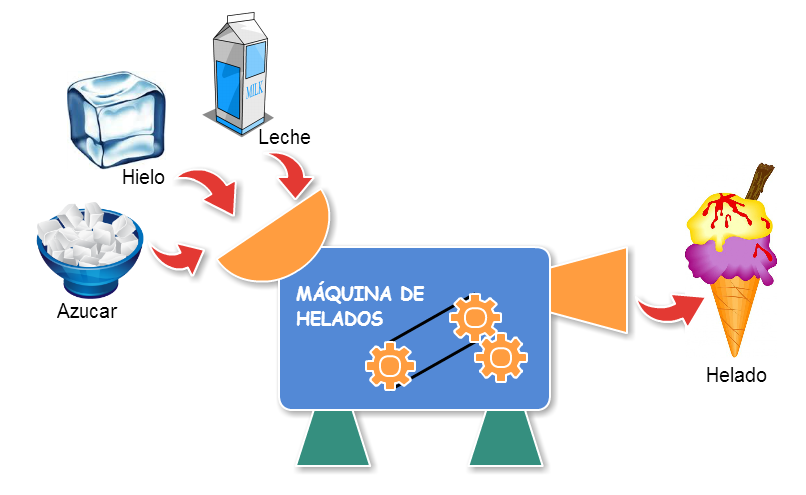

*Tomado de *[*Currículos Exploratorios*](http://contenidos.sucerman.com/nivel3/web2/unidad4/leccion4.html)*.*

Si bien una función puede realizar tareas tanto sencillas como complejas, todas tienen ciertas características en común.

Una función se caracteriza por tener:

- **Un nombre** para llamarla.

- Una, varias o ninguna **entrada** (*input*) que solicita. También se le conoce como **argumento**.

- Una, varias o ninguna **salida** (*output*) que devuelve.

Por ejemplo, la función `sqrt` (raíz cuadrada) tiene:

- **Un nombre:** `sqrt`.

- **Una entrada:** un escalar, vector o matriz numérica.

- **Una salida:** la raíz cuadrada del arreglo ingresado.

sqrt([1 5 3 9;1 2 5 4])

ans =     1.0000    2.2361    1.7321    3.0000
    1.0000    1.4142    2.2361    2.0000


## Conocer el número de entradas y salidas de una función

### Funciones `nargin` y `nargout`

La función `nargin` permite conocer el número máximo de entradas que solicita una función.

nargin sqrt

ans = 1

nargin max

ans = 4

La función `nargout` permite conocer el número máximo de salidas que devuelve una función.

nargout max

ans = 2

¿Siempre una función tiene un número máximo determinado de entradas o salidas? Pues no, no siempre. Existen funciones que tienen un número máximo indeterminado de entradas o salidas, por lo que devuelven `-1`.

nargin plot

ans = -1

#### Observación

La función `plot` permite crear gráficos bidimensionales y acepta una cantidad indeterminada de argumentos. Esta función se la estudiará más adelante.

## Funciones con una entrada y salida

Existen funciones de MATLAB que trabajan con una entrada y devuelven una salida.

Recordemos que la mayoría de funciones de MATLAB están vectorizadas, por lo que las entradas pueden ser escalares, vectores o matrices.

nargin exp

ans = 1

nargout exp

ans = 1

exp([1 5 8 9 3 ])

ans = 1.0e+03 *

    0.0027    0.1484    2.9810    8.1031    0.0201


## Funciones con varias entradas y salidas

A diferencia de las funciones con una entrada y una salida, la mayoría funciones de MATLAB reciben varias entradas y devuelven varias salidas.

Las entradas son sencillas de ingresar puesto que se las separa con comas `,`, mientras que para obtener las distintas salidas se utiliza un vector.

**Figura 2.** Solicitar múltiples salidas.

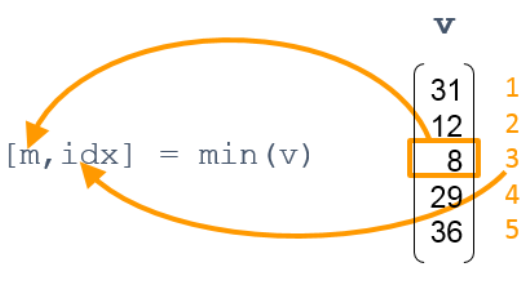

*Tomado de la documentación oficial de MATLAB.*

v=[31 12 8 29 36]

v =     31    12     8    29    36


[m,idx]=min(v)

m = 8

idx = 3

## Omitir entradas y/o salidas de una función

Para omitir entradas de una función se puede utilizar una matriz vacía `[]` como argumento. Esto permitirá saltar ese argumento para ingresar el siguiente. Por otra parte, para omitir una salida de una función se utiliza la tilde de la eñe  `~`, lo cual permite solicitar la siguiente salida.

Empecemos omitiendo entradas y para esto utilizaremos la función `max`.

maxvalues=max([8 1 -2 0 5; 2 0 0 -8 8],[],2)

maxvalues =      8
     8


La función `max` permite ingresar varias entradas. No obstante, para saltar la segunda entrada (puesto que si se ingresa compararía cada elemento de la matriz con esta entrada) se utiliza la matriz vacía `[]`, lo que permite indicar que se busca el número máximo por filas en lugar de una comparación.

Ahora veamos el mismo ejemplo, pero analicemos las salidas.

[~,dixmax]=max([8 1 -2 0 5; 2 0 0 -8 8],[],1)

dixmax =      1     1     2     1     2


La función `max` devuelve hasta dos salidas: la primera salida es el elemento máximo por fila, columna o de toda la matriz, mientras que la segunda salida son los índices del elemento máximo.

En este caso, si únicamente nos interesan los índices del número máximo por columna, entonces podemos omitir la primera salida.

## Anidar funciones

En ocasiones quizá no sea tan útil aplicar una función a la vez. En lugar de ello se puede anidar las funciones (trabajar con funciones dentro de funciones) para optimizar el trabajo.

No obstante, no es necesario exagerar en la anidación puesto que abusar de ésta genera que el código sea difícil de leer y entender.

cos(deg2rad(90))

ans = 6.1232e-17

## Material adicional

- [Función `nargin`](https://www.mathworks.com/help/matlab/ref/nargin.html)

- [Función `nargout`](https://www.mathworks.com/help/matlab/ref/nargout.html)